# BME705: Rehabilitation Engineering

## Lab 4: 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BME705: Rehabilitation Engineering
% Lab 4: 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Name: Tanvir Hassan, Ilina Petrova
% Student ID: 501104056, 501126967

#### Loading Le Files

clear; clc; close all;
signals = cell(2, 1);
[signals{1}] = audioread("voice_signal_9.wav");
[signals{2}, fs] = audioread("voice_signal_10.wav");

### PART 1

% 

#### **1.1 **

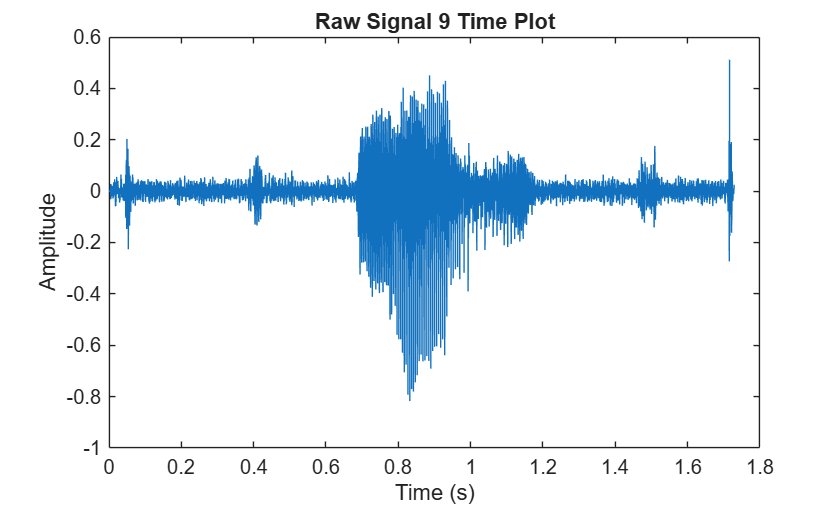

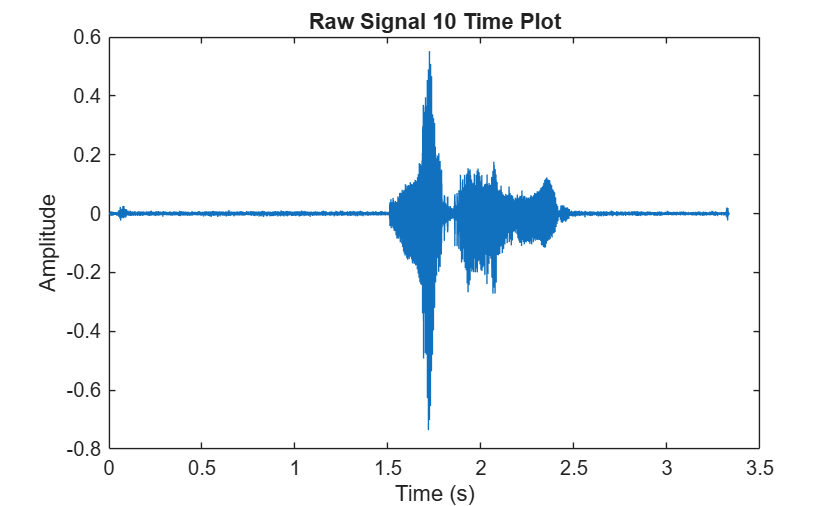

titles = {"Signal 9", "Signal 10"};

%% Plot Signals
for i = 1:length(signals)
   signal = signals{i};
   figure;
   plot((0:length(signal)-1)/fs, signal)
   title(sprintf("Raw %s Time Plot", titles{i}));
   xlabel("Time (s)");
   ylabel("Amplitude");
end

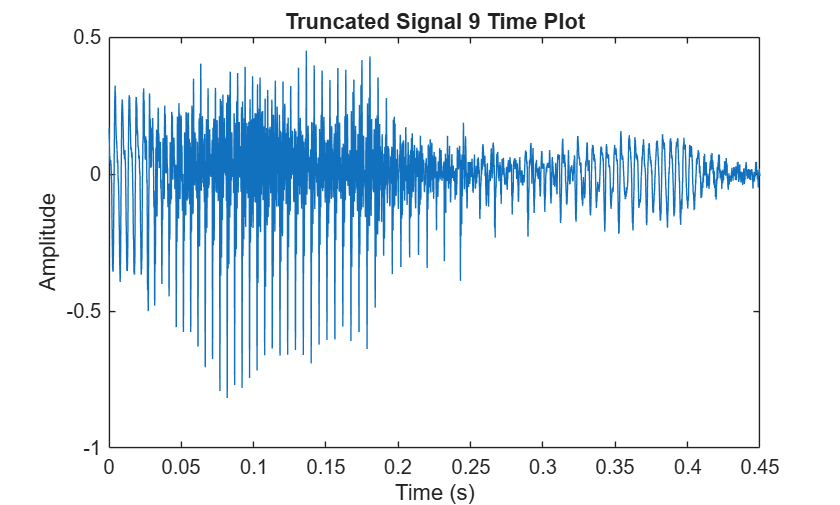

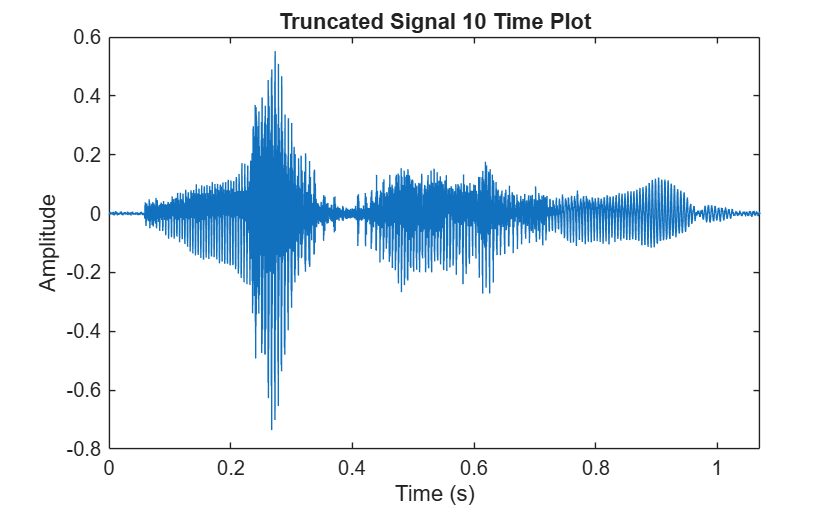

%% Truncate
signals{1} = signals{1}(0.25*fs:1.2*fs);
signals{2} = signals{2}(1.45*fs:2.52*fs);

i1 = max(1, floor(0.5*fs));
i2 = min(numel(signals{1}), floor(1.2*fs));
signals{1} = signals{1}(i1:i2);
% Plot the truncated signals
for i = 1:length(signals)
   signal = signals{i};
   figure;
   plot((0:length(signal)-1)/fs, signal);
   title(sprintf("Truncated %s Time Plot", titles{i}));
   xlabel("Time (s)");
   ylabel("Amplitude");
   xlim([0, length(signal)/fs]); % Set x-axis limits to match the time duration of the signal
end

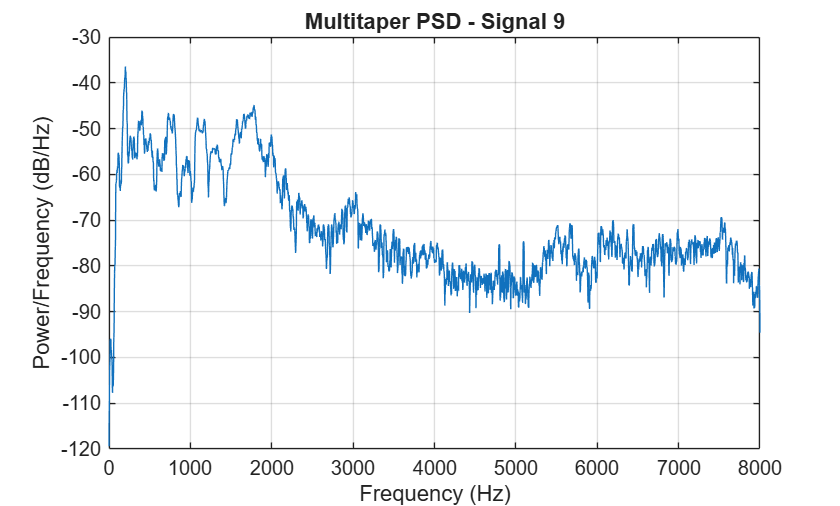

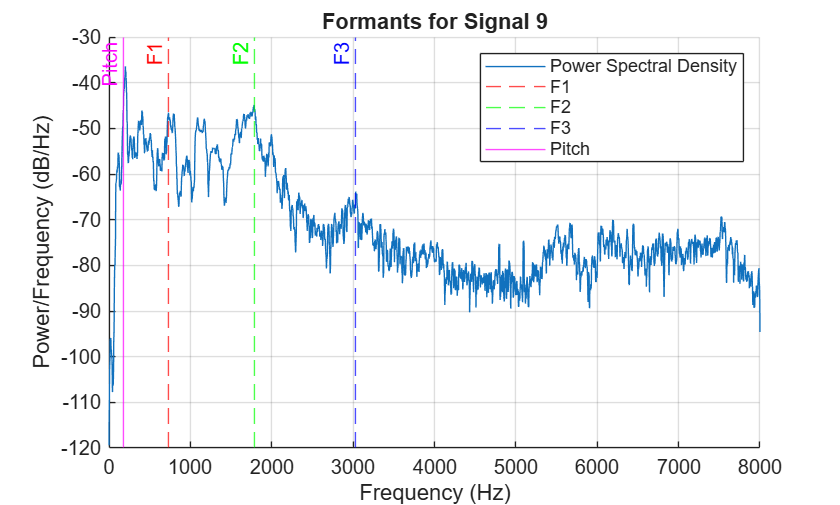

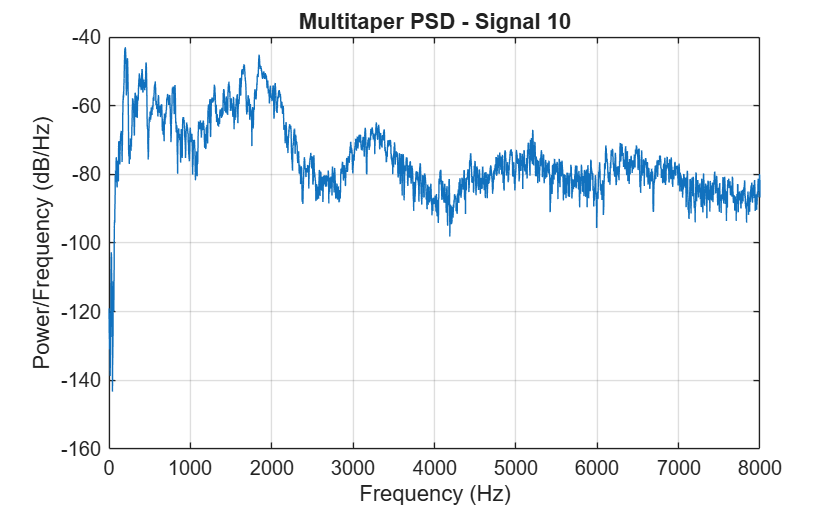

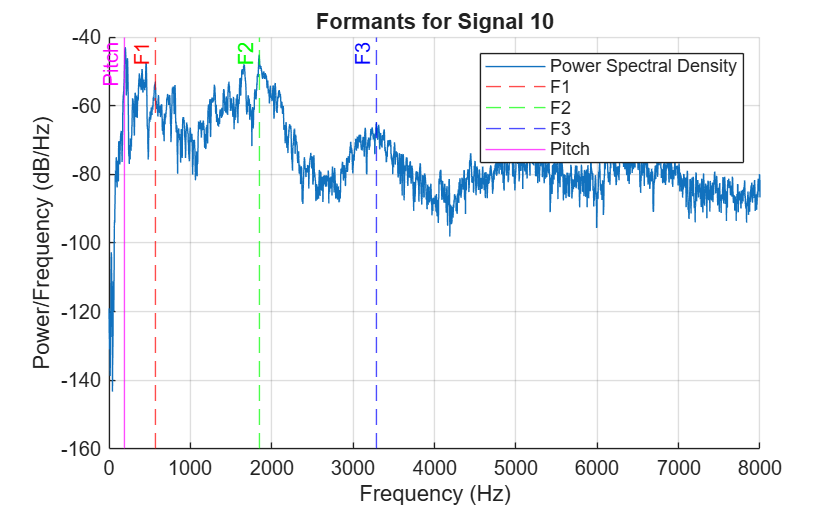

%signals{2} = signals{2}(floor(1.45*fs):floor(2.52*fs)); % Ensure correct indexing for the second signal

%% Initialize tables for pitch and formants
pitch_values = zeros(2, 1);
formant_values = zeros(2, 3); % Columns for F1, F2, and F3
for i = 1:length(signals)
   signal = signals{i};
   % Calculate pitch
   [pitch_vals, pitch_times] = pitch(signal, fs); % Pitch in Hz
   pitch_values(i) = mean(pitch_vals); % Average pitch for the signal
  
   % Estimate power spectral density using pmtm (Multitaper Method)
   NW = 4; % Time-bandwidth product
   [Pxx, f] = pmtm(signal, NW, [], fs);
   % Plot the multitaper power spectral density
   figure;
   plot(f, 10*log10(Pxx));
   title(sprintf('Multitaper PSD - %s', titles{i}));
   xlabel('Frequency (Hz)');
   ylabel('Power/Frequency (dB/Hz)');
   grid on;
   % Extract formants
   % F1: 500-1000 Hz
   F1_range = f(f >= 500 & f <= 1000);
   P1_range = Pxx(f >= 500 & f <= 1000);
   [~, idx1] = max(P1_range);
   F1 = F1_range(idx1);
   % F2: 1500-2500 Hz
   F2_range = f(f >= 1500 & f <= 2500);
   P2_range = Pxx(f >= 1500 & f <= 2500);
   [~, idx2] = max(P2_range);
   F2 = F2_range(idx2);
   % F3: 2500-3500 Hz
   F3_range = f(f >= 2500 & f <= 3500);
   P3_range = Pxx(f >= 2500 & f <= 3500);
   [~, idx3] = max(P3_range);
   F3 = F3_range(idx3);
   
   % Plot formants
   figure;
   hold on;
   plot(f, 10*log10(Pxx), 'DisplayName', 'Power Spectral Density');
   xline(F1, 'r--', 'F1', 'LabelHorizontalAlignment', 'left', 'DisplayName', 'F1');
   xline(F2, 'g--', 'F2', 'LabelHorizontalAlignment', 'left', 'DisplayName', 'F2');
   xline(F3, 'b--', 'F3', 'LabelHorizontalAlignment', 'left', 'DisplayName', 'F3');
   xline(pitch_values(i), 'm', 'Pitch', 'LabelHorizontalAlignment', 'left', 'DisplayName', 'Pitch');
   title(sprintf('Formants for %s', titles{i}));
   xlabel('Frequency (Hz)');
   ylabel('Power/Frequency (dB/Hz)');
   legend show;
   grid on;
   hold off;
   % Store formant values
   formant_values(i, :) = [F1, F2, F3];
end

%% Display results in a table
results_table = table(titles', pitch_values, formant_values(:, 1), formant_values(:, 2), formant_values(:, 3), ...
   'VariableNames', {'Signal', 'Pitch (Hz)', 'F1 (Hz)', 'F2 (Hz)', 'F3 (Hz)'});
disp(results_table);

        Signal         Pitch (Hz)    F1 (Hz)    F2 (Hz)    F3 (Hz)
    _______________    __________    _______    _______    _______

    {["Signal 9" ]}      178.01      730.47     1783.2     3031.2 
    {["Signal 10"]}      191.06      568.85     1844.7     3285.2 

